load ('Samsung_30Q_18650_pack.mat');
load ('VoltaicSystems_P110.mat');

addpath(genpath("Functions"));
addpath("Simulink/");

picture_path = "/home/teo/Documents/Kolegiji/Diplomski_rad/Materijal/MATLAB/Strujni/Slike_CV";
mat_files_path = "/home/teo/Documents/Kolegiji/Diplomski_rad/Materijal/MATLAB/Strujni/Mat_files";

% Switching frequency:
boost.f = 1 * 10^5; % [Hz]
boost.T = 1/boost.f;

% Measurement filter cut-off:
boost.mfc = 2000; %[Hz]
boost.Tmfc = 1/(2*pi*boost.mfc);

% Granicni uvjet filter:
boost.Tgf = 1/(pi*1000);

% Maximum duty cycle that can be achieved:
boost.D_max = 1 - pv_data.Umpp/Bat.Ubat_nom; % MPP mode of operation

% Passive elements:
boost.Rt = 1*10^5;
boost.RL = 10 * 10^-3;
boost.Ru = 1;
boost.L = 40 * 10^-6;
boost.Cu = 1500 * 10^-6;
boost.Ci = 1200 * 10^-6;
boost.Cbat = Bat.Qbat_tot/(Bat.Ubat_charged - Bat.Ubat_cut_off);

## PV resistance:

% CCM:
pv_in.G = 800;     %[W/m^2]
pv_in.t = 25;       %[deg]
pv_in.ramp = 1;     %[/]

pv_ccm = calc_pv_res("Solar_v2", pv_in);


% DCM
pv_in.G = 800;     %[W/m^2]
pv_in.t = 25;       %[deg]
pv_in.ramp = 1;     %[/]

pv_dcm = calc_pv_res("Solar_v2", pv_in);

clear pv_in;

## Pick operating point:

% Pick operating point for simulation:

% CCM:
Upv_op = pv_ccm.Umpp;
idx = find(pv_ccm.Upv >= Upv_op, 1);
Ipv_op = pv_ccm.Ipv(idx);

ccm_in.Upv_op = Upv_op;
ccm_in.Ipv_op = Ipv_op;

%DCM
Upv_op = pv_dcm.Umpp;
idx = find(pv_dcm.Upv >= Upv_op, 1);
Ipv_op = pv_dcm.Ipv(idx);

dcm_in.Upv_op = Upv_op;
dcm_in.Ipv_op = Ipv_op;

clear idx;
clear Upv_op Ipv_op;

## Step input Settings:

% Step input settings:
stepp.step_time = 20 * 10^-3; % [ms]
% stepp.sim_time = 50 * 10^-3; % [ms]
stepp.sim_time = 0.5;

% Ir, Refrence current:
stepp.ir01 = ccm_in.Ipv_op + 0.05;
stepp.ir02 = dcm_in.Ipv_op; + 0.05;

[~, idx1] = min(abs(pv_ccm.Ipv - stepp.ir01));
[~, idx2] = min(abs(pv_dcm.Ipv - stepp.ir02));

stepp.upv1 = pv_ccm.Upv(idx1);
stepp.upv2 = pv_dcm.Upv(idx2);

% CCM:
stepp.d1 = ccm_op_CV(boost, Bat, pv_ccm).D0;
stepp.d2 = dcm_op_CV(boost, Bat, pv_dcm).D0;

clear idx1 idx2;

## Irradiance signal:

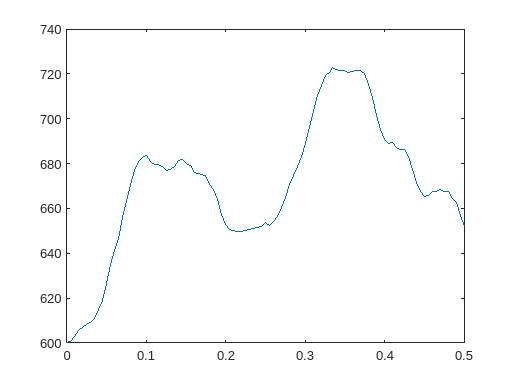

% GI_signal = Irradiance_signal(stepp.sim_time, 0.01, 200, 1000);
GI_signal_real = irradiance_signal_real(0.5, 0.005, 200, 1000);


figure();
% GI_signal.plot();
% hold on;
plot(GI_signal_real.Time, GI_signal_real.Data);

## Racunanje MPP za signal ozracenja:

% pv_in.t = 25;       %[deg]
% pv_in.ramp = 1;     %[/]    
% 
% for j = 1:numel(GI_signal_real)
%     pv_in.G = GI_signal_real(j);     %[W/m^2]
% 
%     simIn = Simulink.SimulationInput("Solar_v2");
%     paramNames = fieldnames(pv_in);
% 
%     % inject variables into simulink:
%     for i = 1:numel(paramNames)
%         simIn = simIn.setVariable(paramNames{i}, pv_in.(paramNames{i}));
%     end
% 
%     SimOut = sim(simIn);
%     Upv = SimOut.get("Upv_sim").Data;
%     Ipv = SimOut.get("Ipv_sim").Data;
% 
%     Ppv = Upv .* Ipv;
% 
%     pv_out.Pmax(j) = max(Ppv);
%     pv_out.G(j) = GI_downsampled(j);
% end

% data = [GI_signal_real.Data(:), pv_out.Pmax(:)];  % oba Nx1
% G_real_signal = timeseries(data, GI_signal_real.Time);


% save("Realisticno_ozracenje.mat", "G_real_signal")

## Steady state operating point parameters:

ccm_op_mpp = ccm_op_MPP(boost, Bat, pv_ccm);
Upv0 = ccm_op_mpp.Upv0

Upv0 = 5.7000

Ipv0 = ccm_op_mpp.Ipv0

Ipv0 = 1.4690

Ubat0 = ccm_op_mpp.Ubat0

Ubat0 = 10.8000

Im0 = ccm_op_mpp.Im0

Im0 = 0.6544

m0 = ccm_op_mpp.m0

m0 = 3.0002e+04

ro = ccm_op_mpp.ro

ro = 0.5652

L_lim = ccm_op_mpp.L_lim

L_lim = 6.0350e-05

D0 = ccm_op_mpp.D0

D0 = 0.4722

Ir_lim = ccm_op_mpp.Ir_lim

Ir_lim = 0.8146


dcm_op_mpp = dcm_op_MPP(boost, Bat, pv_dcm);
Upv0 = dcm_op_mpp.Upv0

Upv0 = 5.7000

Ipv0 = dcm_op_mpp.Ipv0

Ipv0 = 1.4690

Ubat0 = dcm_op_mpp.Ubat0

Ubat0 = 10.8000

m0 = dcm_op_mpp.m0

m0 = 3.0002e+04

ro = dcm_op_mpp.ro

ro = 1.4897

D0 = dcm_op_mpp.D0

D0 = 0.8516


sim_op = ccm_op_mpp;

clear Upv0 Ipv0 Ubat0 Im0 m0 ro L_lim D0 Ir_lim;

## Plant model:

% CCM-MPP:
[Gp_ccm_mpp, ccm_sys_const_mpp] = ccm_sys_MPP(ccm_op_mpp, boost);

Gp_ccm_mpp

Gp_ccm_mpp =
 
     -2.193
  -------------
  0.00582 s + 1
 
Continuous-time transfer function.
Model Properties



1/ccm_sys_const_mpp.Tn

ans = 171.8131


% DCM-MPP:
[Gp_dcm_mpp, dcm_sys_const_mpp] = dcm_sys_MPP(dcm_op_mpp, boost);

Gp_dcm_mpp

Gp_dcm_mpp =
 
      -5.78
  -------------
  0.00582 s + 1
 
Continuous-time transfer function.
Model Properties


## Regulator (tehnicki optimum):

[G_ccm_mpp_full, ccm_mpp_reg_param] = TO_regulator(Gp_ccm_mpp, ccm_sys_const_mpp);
ccm_mpp_reg_param.KR

ans = -0.4560

ccm_mpp_reg_param.Ti

ans = 0.0058


[G_dcm_mpp_full, dcm_mpp_reg_param] = TO_regulator(Gp_dcm_mpp, dcm_sys_const_mpp);
dcm_mpp_reg_param.KR

ans = -0.1730

dcm_mpp_reg_param.Ti

ans = 0.0058


mpp_m0 = ccm_op_mpp.m0;

save(mat_files_path + "/MPP_param.mat", "ccm_mpp_reg_param", "dcm_mpp_reg_param", "mpp_m0");

clear mpp_m0;

## Regulator (simetricni optimum, zeta i PM):

% Ulazni parametri:
Gp = Gp_ccm_mpp;
param = ccm_sys_const_mpp;
Mp = 0.20;
%%%%%%%%%%%%%%%%%%

zeta = sqrt((log(Mp)^2)/(pi^2 + (log(Mp))^2))

% PM = deg2rad(zeta * 100)
PM = atan((2*zeta)/(sqrt(sqrt(4*zeta^4 + 1) - 2*zeta^2)))

Kp = param.K;
wp = 1/param.Tn
a = rad2deg(PM)/14;

wc = -wp*(tan(PM-pi/2)-a)/(1+a*tan(PM-pi/2))

wi = wc/a

Ti = abs(1/wi)
KR = ((wc^2)*sqrt(wp^2 + wc^2))/(Kp*sqrt(wi^2 + wc^2))

GR = tf([KR, KR/Ti], [1, 0]); 

G_full = GR * Gp;

w = logspace(0, 4, 1000);
draw_bode(G_full, w);

## Regulator (simetricni optimum, standardno):

% Ulazni parametri:
Gp = Gp_ccm_mpp;
param = ccm_sys_const_mpp;
Mp = 0.20;
%%%%%%%%%%%%%%%%%%

a = 3.57;
Kp = param.K;
wp = 1/param.Tn

wc = wp/a
wi = wc/a

Ti = abs(1/wi)
KR = ((wc^2)*sqrt(wp^2 + wc^2))/(Kp*sqrt(wi^2 + wc^2))

## PID tuner:

KR = PI.Kp
Ti = PI.Kp/PI.Ki

## Bode:

w = logspace(0, 4, 1000);
draw_bode(Gp_ccm_mpp, w);


## test:

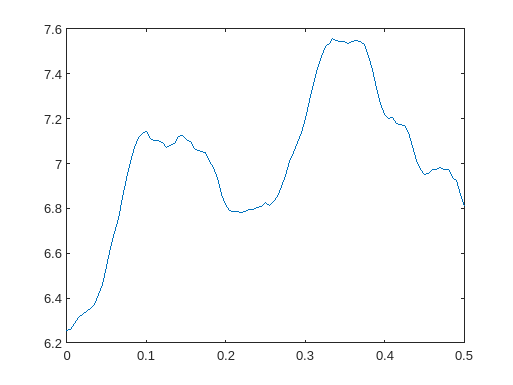

figure();
plot(G_real_signal.Time, G_real_signal.Data(:,2))

## Simuliranje rada

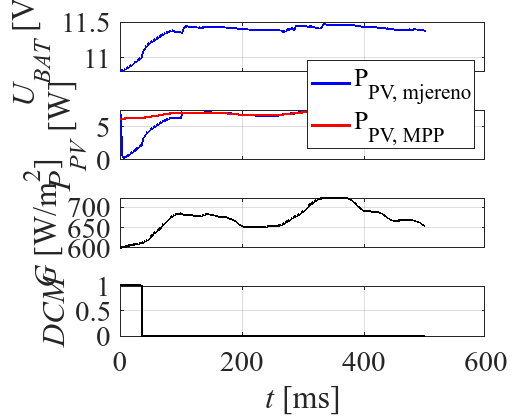

% Input irradiance signal:
% GI = timeseries(G_real_signal.Data(:,1), G_real_signal.Time);

% MPP_response = sim("Regulacija_sim/maximum_power2.slx");

t = MPP_response.get("Ubat").Time * 1000;
Ubat = MPP_response.get("Ubat").Data;
Ppv = MPP_response.get("Ppv").Data;
Gir = MPP_response.get("Gir").Data;
t_dcm = MPP_response.get("DCM").Time * 1000;
DCM = MPP_response.get("DCM").Data;

t_pv_real = G_real_signal.Time * 1000;
Ppv_real = G_real_signal.Data(:,2);

% G_interp = interp1(t_pv_real, Ppv_real, t, 'linear', 'extrap');

step = 10;  % plot every 10th sample (you’ll still have 1000 pts over 0.1s)
t_plot = t(1:step:end);
Ubat_plot = Ubat(1:step:end);
Ppv_plot = Ppv(1:step:end);
Gir_plot = Gir(1:step:end);
DCM_plot = DCM(1:step:end);

% for 11 x 9 (W x H)
width_px = round(11/2.54 * 300); % ~1335 pixels
height_px = round(9/2.54 * 300); % ~1146 pixels

fig = figure('Units','pixels', 'Position', [100 100 width_px height_px]); % W x H

% Plotting a 4 x 1 array of graphs:
layout = tiledlayout(4,1);
layout.TileSpacing = 'compact';
layout.Padding = 'compact';

nexttile;
plot(t, Ubat, '-b', 'LineWidth', 1.8);
hold on;
grid on;
ylabel("\it{U_{BAT}}\rm [V]");
set(gca, 'FontSize', 22, 'FontName', 'Times New Roman', 'XTickLabel', [], 'LineWidth', 1.2);

nexttile;
plot(t, Ppv, '-b', 'LineWidth', 1.6);
hold on;
grid on;
plot(t_pv_real, Ppv_real, '-r', 'LineWidth', 1.6);
ylabel("\it{P_{PV}}\rm [W]");
legend("P_{PV, mjereno}", "P_{PV, MPP}", 'Location', 'southeast');
set(gca, 'FontSize', 22, 'FontName', 'Times New Roman', 'XTickLabel', [], 'LineWidth', 1.2);

% nexttile -> for IL

nexttile;
plot(t, Gir, '-k', 'LineWidth', 1.6);
grid on;
ylabel("\it{G}\rm [W/m^2]");
set(gca, 'FontSize', 22, 'FontName', 'Times New Roman', 'XTickLabel', [], 'LineWidth', 1.2);

nexttile;
stairs(t_dcm, DCM, '-k', 'LineWidth', 1.6);
grid on;
ylabel("\it{DCM}\rm");
xlabel("\it{t}\rm [ms]");
set(gca, 'FontSize', 22, 'FontName', 'Times New Roman', 'LineWidth', 1.2);



exportgraphics(gcf, picture_path + "/MPP_sim.png", 'Resolution', 300);

## PV ulazni param:

pv_in.G = 1000;     %[W/m^2]
pv_in.t = 25;       %[deg]
pv_in.ramp = 1;     %[/]

pv_in.G = 1000; 
pv_1000 = calc_pv_res("Solar_v2", pv_in);
pv_in.G = 500;
pv_500 = calc_pv_res("Solar_v2", pv_in);
pv_in.G = 200;
pv_200 = calc_pv_res("Solar_v2", pv_in);

pv_1000.G = 1000;
pv_500.G = 500;
pv_200.G = 200;

## PV U-I karakteristika:

pv_list = {pv_1000, pv_500, pv_200};
colors = {'b', 'r', [1, 0.5, 0]};

fig = plot_pv_characteristics(pv_list, colors)
exportgraphics(gcf, picture_path + "/pv_irradiance_characteristics.png", 'Resolution', 300);

## PV P-U karakteristika:

% Figure size ~11x9 cm
width_px = round(11/2.54 * 300);
height_px = round(9/2.54 * 300);
fig = figure('Units','pixels', 'Position', [100 100 width_px height_px]);

% Font settings
set(fig, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 24);
set(fig, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 24);

plot(pv_1000.Upv, pv_1000.Ppv, '-k', 'LineWidth', 2);  % <-- main P-V plot
hold on;

% Grid settings (make it pronounced)
grid on;

% MPP guide lines
yline(pv_1000.Pmpp, '--k', 'LineWidth', 1.6);
xline(pv_1000.Umpp, '--k', 'LineWidth', 1.6);

% Axis labels
xlabel('${Napon, U_{PV} [V]}$', 'Interpreter', 'latex');
ylabel('${Snaga, P_{PV} [W]}$', 'Interpreter', 'latex');

% --- Set only Umpp and Pmpp as ticks ---
xticks(pv_1000.Umpp);
yticks(pv_1000.Pmpp);

xticklabels({'$U_{MPP}$'});
yticklabels({'$P_{MPP}$'});
set(gca, 'TickLabelInterpreter', 'latex');

% Tick appearance
ax.TickLength = [0.015 0.015];
ax.TickLabelInterpreter = 'latex';
ax.TickLabelInterpreter = 'latex';

grid on;
% Add MPP marker
plot(pv_1000.Umpp, pv_1000.Pmpp, 'ok', 'MarkerFaceColor', 'k', 'MarkerSize', 6);

% --- Annotations ---
text(pv_1000.Umpp + 0.1, pv_1000.Pmpp + 0.2, ...
     "$\frac{dP}{dV} = 0$", ...
     'Interpreter', 'latex', 'FontSize', 18);

text(pv_1000.Umpp - 2.2, pv_1000.Pmpp - 2.5, ...
     "$\frac{dP}{dV} > 0$", ...
     'Interpreter', 'latex', 'FontSize', 18);

text(pv_1000.Umpp + 0.8, pv_1000.Pmpp - 2.0, ...
     "$\frac{dP}{dV} < 0$", ...
     'Interpreter', 'latex', 'FontSize', 18);

% Limits
xlim([0, max(pv_1000.Upv)]);
ylim([0, max(pv_1000.Ppv)*1.05]);

% Grid again, just to be safe
grid on;


% Ensure text is black
exportgraphics(gcf, picture_path + "/pv_incremental_conductance.png", 'Resolution', 300);